# **EllipticNome**

[Elliptic nome](https://dlmf.nist.gov/search/search?q=nome)

## Definition


$$q\left(m\right)\equiv \left\lbrace \begin{array}{cc}
\mathrm{exp}\left(-\pi \frac{\mathit{K'}\left(m\right)}{K\left(m\right)}\right) & m\ge 0\\
-\mathrm{exp}\left(-\pi \frac{\sqrt{1-m}\mathit{K'}\left(\frac{1}{1-m}\right)}{K\left(m\right)}\right) & m<0
\end{array}\right.$$



$$\mathit{\mathbf{q}}\left(k\right)\equiv q\left(k^2 \right)$$


where *k *is the modulus and *m *is the parameter, $K\left(m\right)$ and $\mathit{K'}\left(m\right)$ are complete and complementary complete elliptic integral of the first kind. 

Domain:$-\infty <m\le 1$.  For the specified domain, the  codomain is the set of real numbers.

Basic features:

Special values:

$q\left(-\infty \right)=-1$,   $q\left(0\right)=0$,   $q\left(\frac{1}{2}\right)=\mathrm{exp}\left(-\pi \right)$,   $q\left(1\right)=1$

Identities:

## Syntax

Y = EllipticNome(K)

y = elnome(k)

Y = mEllipticNome(M)

y = melnome(m)

## Description

**Y = EllipticNome(K)** returns  $\mathit{\mathbf{q}}\left(k\right)$ for each element of the array K (modulus).  K must be real array or scalar. **EllipticNome** is the wrapper function which calls the functions **elnome** element-wise via the function **ufun1**.

**y = elnome(k)** returns $\mathit{\mathbf{q}}\left(k\right)$ for  the modulus k. It is assumed that  k is  real scalar. y is NaN if k is invalid or convergence failed. **elnome** is the wrapper function which calls the functions **melnome**.

**Y = mEllipticNome(M) **returns $q\left(m\right)$ for each element of the array M (parameter). M must be real array or scalar. **mEllipticNome** is the wrapper function which calls the function **melnome** element-wise via the function **ufun1**.

**y = melnome(m) **returns the elliptic nome $q\left(m\right)$ for   the parameter m. It is assumed that  m is real scalars without check. y is NaN if  m is invalid or convergence failed.   **melnome** calculte  $q\left(m\right)$ using the functions **melK** and **melCK  **([1])

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5; 
[elnome(k), EllipticNome(k), melnome(k^2), mEllipticNome(k^2)]

ans =    0.017972387008967   0.017972387008967   0.017972387008967   0.017972387008967


Accuracy

fprintf('%.16g\n',elnome(0.5))

0.01797238700896724


% Maple 0.01797238700896724_00

fprintf('%.16g\n',melnome(-4))

-0.09927369733882502


% Maple  -0.09927369733882489_70


[MATLAB example](https://www.mathworks.com/help/symbolic/ellipticnome.html)

disp(mEllipticNome([0 1/2 1]))

                   0   0.043213918263772   1.000000000000000



Special values

melnome(0)

ans = 0

disp(melnome(1/2)-exp(-pi) ) 

     0



disp(melnome(1) - 1)  

     0



**Vector input**

K = [0, 1/sqrt(2), 1]; % |K|<1
disp(EllipticNome(K))

                   0   0.043213918263772   1.000000000000000



**Matrix input**

M = [-2, -3, -4; 1, 1/2, 1/3];
disp(mEllipticNome(M))

  -0.068237827745338  -0.085795733702195  -0.099273697338825
   1.000000000000000   0.043213918263772   0.025319913366285



## **Graphs **

**Example 1**

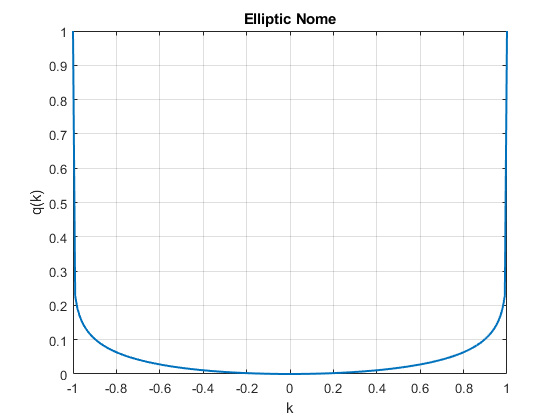

figure
k=-1:0.01:1;
plot(k,EllipticNome(k),'LineWidth',1.5)
xlabel('k')
ylabel('q(k)')
title('Elliptic Nome')
grid on

**Example 2**

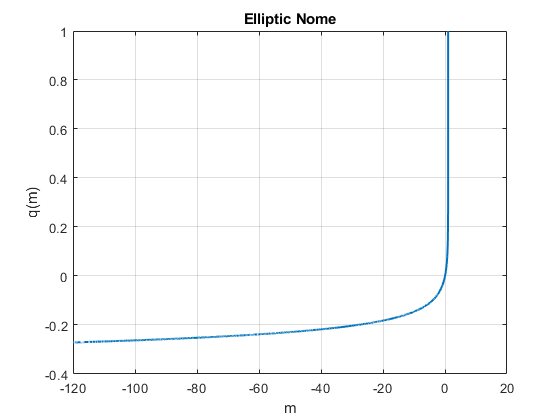

figure
m=-120:0.01:1;
plot(m,mEllipticNome(m),'LineWidth',1.5)
xlabel('m')
ylabel('q(m)')
title('Elliptic Nome')
grid on

**Example 3**

[MATLAB example](https://www.mathworks.com/help/symbolic/ellipticnome.html)

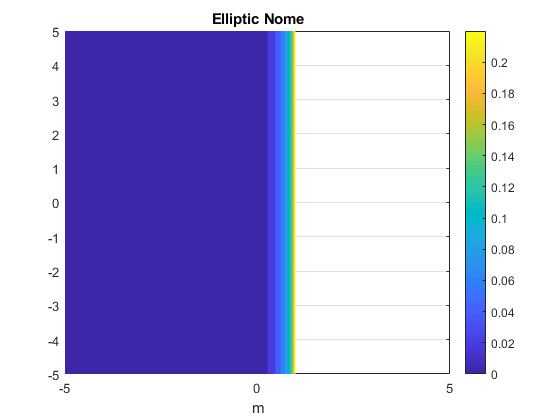

figure
f = @(m)mEllipticNome(m);
fcontour(f,'Fill','on','LevelList',0:0.02:1,'MeshDensity',200)
title('Elliptic Nome')
xlabel('m')
colorbar
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22.2)

## **References**

## See Also